clc
clear 
clear ZX
global Paras %#ok<GVMIS>该行注释的符号用于屏蔽matlab中的warning
mode1="公式计算";
%mode2="单图结果";
%mode2="T";
mode2="W0";

%TODO for循环绘制多个图像/导出参数为格式xls或其他格式
%TODO 绘制某个变量单独变化对结果的影响，一个图像多条曲线
% 要能据此画出三维图像

Paras=[60,0.15,1.1806,0.005359,0.003731,0.02767];

global ZX n1;
n1=1;
ZX=zeros(24001,4,5);
% for i=(60:5:80)
%     i%i不注释用于直观查看仿真速度
% Paras(1)=i;
for i=(0.15:0.05:0.35)
    i%i不注释用于直观查看仿真速度
Paras(2)=i;

i = 0.1500

i = 0.2000

i = 0.2500

i = 0.3000

i = 0.3500

## 相关常数的赋值与计算

global a0 a1 b0 b1 thetap0 thetap1 thetat0 alpha Wt W0 f R T; %#ok<GVMIS>
% 统一使用全局变量，方便迭代函数使用
a0=2.459143e-2;
a1=2.791111e-7;
b0=4.146419e-2;
b1=4.099739e-7;
thetap0=8.093258e-6;
thetap1=4.313689e3;
thetat0=2.712523e-7;
alpha=5.136868e-1;
Wt=2.724429e3;
%上述参数会计算出另外4个参数值，和表上的对不上，可能要算一下。
W0=Paras(2);%给出参数，引发剂重量百分比浓度0.15%，可修改

f=0.65;%58
R=8.314;%59
T=Paras(1)+273.15;%333.15华氏度;%60摄氏度

global kd kp0 kt0 kfm dm dp; %#ok<GVMIS>
kd=1.29e15*exp(-127600/(R*T));%52
kp0=2.17e7*exp(-32466.7/(R*T));%53
kt0=1.629e9*exp(-6255.45/(R*T));%54
kfm=7.513e6*exp(-55583.63/(R*T));%55
dm=(0.9232-8.64e-4*(T-273.15))*1000;%56
dp=(1.0652-6.02e-4*(T-273.15))*1000;%57

global epsilon M0 I0; %#ok<GVMIS>
epsilon=dm/dp-1.0;%61
M0=dm/104.14;%62含常数
I0=W0*dm/15400;%63含常数

%四个常数写成函数如下
global A B thetap thetat; %#ok<GVMIS>
if(mode1 == "公式计算")
    A=@(T) a0-a1*(T-366.65)^2;%65
    B=@(T) b0-b1*(T-366.65)^2;%66
    thetap=@(T) thetap0*exp(thetap1/T);%67
    thetat=@(T,I0) thetat0*I0^-alpha*exp(Wt/T);%68
    % 由于用公式计算得出的常数与资料内给出的常数不同，可选择直接使用资料给出的常数
    % 改用给的参数时，仿真结果差距比较大
    
else
    A=@(T) Paras(5);
    B=@(T) Paras(6);
    thetap=@(T) Paras(3);
    thetat=@(T,I0) Paras(4);
end

## 根据状态方程求解

Hfun = @(t, State) StateDerivative(t, State);
% 参数
t = [0 4000*60];%2200*60];     % 时间范围
h = 10;       % 时间步长
x0 = [0 0 0 0];   % 初始状态
% 转化率a，即x0(1)初始为0
% 另三个状态变量mu0，mu1，mu2，参与数均聚合度和重均聚合度计算
% 不参与迭代，因而可任意设置初值

%RK4求解
[T1,X1]=ODE_RK4( Hfun,t,h,x0 );
writematrix([T1,X1],'状态变量')
%matlab自带的ode45求解
%[T1,X1]=ode45( Hfun,t(1):h:t(2),x0 );
ZX(:,:,n1)=X1;
n1=n1+1;
end

## 绘图对比

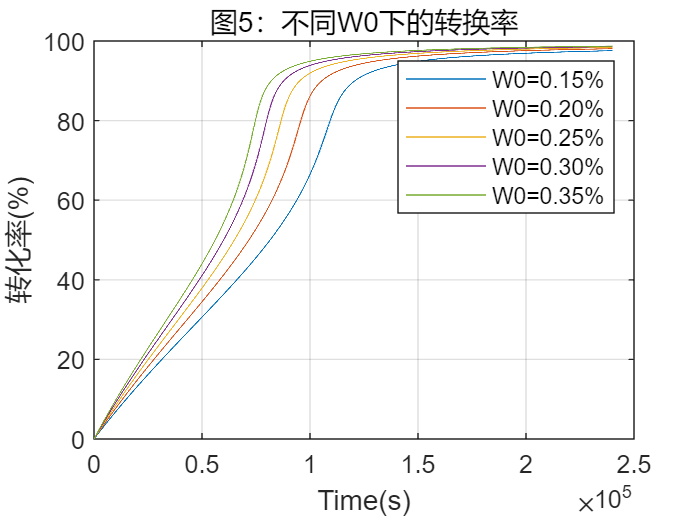

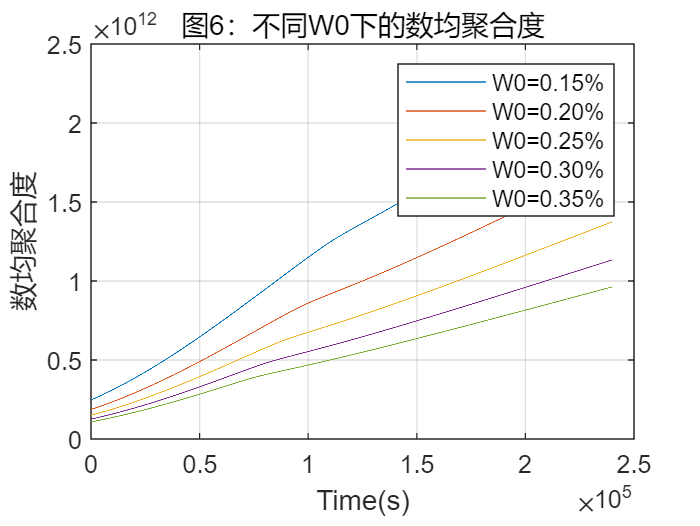

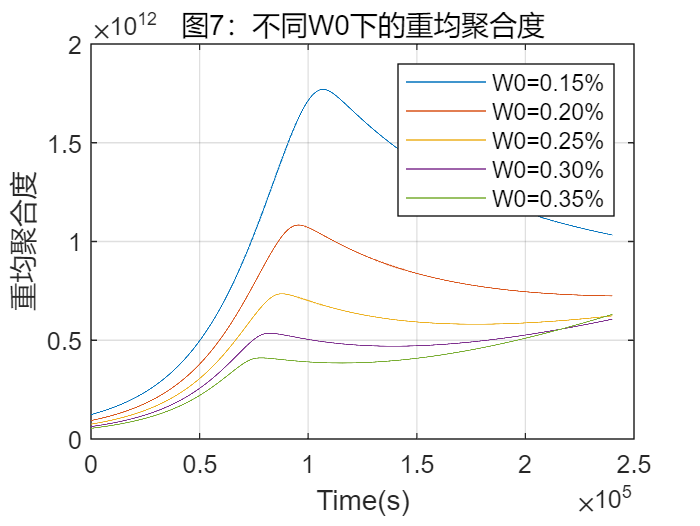


if(mode2=="单图结果")
    figure(1)
    title("图1：直观的关于三个量的仿真结果")
    subplot(311)
    plot(T1,100*X1(:,1))
    xlabel('Time(s)')
    ylabel('转化率（%）')
    grid
    %legend('x','y1','y2')
    subplot(312)
    plot(T1, 104.14*X1(:,3)./X1(:,2))
    xlabel('Time(s)')
    ylabel('数均聚合度')
    grid
    subplot(313)
    plot(T1, 104.14*X1(:,4)./X1(:,3))
    xlabel('Time(s)')
    ylabel('重均聚合度')
    grid
    
elseif(mode2=="T")
    figure('Name', 'My Figure', 'Color', 'w')
    plot(T1,100*ZX(:,1,1),T1,100*ZX(:,1,2),T1,100*ZX(:,1,3),T1,100*ZX(:,1,4),T1,100*ZX(:,1,5))
    xlabel('Time(s)')
    ylabel('转化率(%)')
    title("图2：不同温度下的转换率")
    legend('T=60°C','T=65°C','T=70°C','T=75°C','T=80°C')
    grid;
    figure('Name', 'My Figure', 'Color', 'w')
    plot(T1,104.14*ZX(:,3,1)./ZX(:,2,1),T1,104.14*ZX(:,3,2)./ZX(:,2,2),T1,104.14*ZX(:,3,3)./ZX(:,2,3),T1,104.14*ZX(:,3,4)./ZX(:,2,4),T1,104.14*ZX(:,3,5)./ZX(:,2,5))
    xlabel('Time(s)')
    ylabel('数均聚合度')
     title("图3：不同温度下的数均聚合度")
    legend('T=60°C','T=65°C','T=70°C','T=75°C','T=80°C')
    grid;
    figure('Name', 'My Figure', 'Color', 'w')
    plot(T1,104.14*ZX(:,4,1)./ZX(:,3,1),T1,104.14*ZX(:,4,2)./ZX(:,3,2),T1,104.14*ZX(:,4,3)./ZX(:,3,3),T1,104.14*ZX(:,4,4)./ZX(:,3,4),T1,104.14*ZX(:,4,5)./ZX(:,3,5))
    xlabel('Time(s)')
    ylabel('重均聚合度')
    title("图4：不同温度下的重均聚合度")
    legend('T=60°C','T=65°C','T=70°C','T=75°C','T=80°C')
    grid;
elseif(mode2=="W0")
     figure('Name', 'My Figure', 'Color', 'w')
    plot(T1,100*ZX(:,1,1),T1,100*ZX(:,1,2),T1,100*ZX(:,1,3),T1,100*ZX(:,1,4),T1,100*ZX(:,1,5))
    xlabel('Time(s)')
    ylabel('转化率(%)')
    title("图5：不同W0下的转换率")
    legend('W0=0.15%','W0=0.20%','W0=0.25%','W0=0.30%','W0=0.35%')
    grid;
    figure('Name', 'My Figure', 'Color', 'w')
    plot(T1,104.14*ZX(:,3,1)./ZX(:,2,1),T1,104.14*ZX(:,3,2)./ZX(:,2,2),T1,104.14*ZX(:,3,3)./ZX(:,2,3),T1,104.14*ZX(:,3,4)./ZX(:,2,4),T1,104.14*ZX(:,3,5)./ZX(:,2,5))
    xlabel('Time(s)')
    ylabel('数均聚合度')
    title("图6：不同W0下的数均聚合度")
    legend('W0=0.15%','W0=0.20%','W0=0.25%','W0=0.30%','W0=0.35%')
    grid;
    figure('Name', 'My Figure', 'Color', 'w')
    plot(T1,104.14*ZX(:,4,1)./ZX(:,3,1),T1,104.14*ZX(:,4,2)./ZX(:,3,2),T1,104.14*ZX(:,4,3)./ZX(:,3,3),T1,104.14*ZX(:,4,4)./ZX(:,3,4),T1,104.14*ZX(:,4,5)./ZX(:,3,5))
    xlabel('Time(s)')
    ylabel('重均聚合度')
    title("图7：不同W0下的重均聚合度")
    legend('W0=0.15%','W0=0.20%','W0=0.25%','W0=0.30%','W0=0.35%')
    grid;
end

ODE_RK4

function [T,X,dX] = ODE_RK4( Hfun,t,h,x0 )
% [T,X] = ODE_RK4( Hfun,t,h,x0 ) 4阶龙格-库塔法求解常微分方程
% Hfun为描述状态导数的函数句柄，格式为 dX = Hfun( t,X )
% 必须保证返回dX的格式为行向量
% t为时间节点，可为标量，时间范围为 T = 0:h:t
%             长2向量 ，时间范围为 T = t(1):h:t(2)
%             向量 ，时间范围为 T = t
% h为时间步长，在t的前两种情况下，必须给出h具体值
% 直接给出时间节点t时，h可用[]或任意值占位
% x0为状态量初始值  
% 算法：
%      K1  = Hfun( t(k-1),X(k-1) ) =  dX(k-1)
%      K2 =  Hfun( t(k-1)+h/2,X(k-1)+h*K1/2 )
%      K3 =  Hfun( t(k-1)+h/2,X(k-1)+h*K2/2 )
%      K4 =  Hfun( t(k-1)+h  ,X(k-1)+h*K3 )
%    X(k) =  X(k-1) + (h/6) * (K1 + 2*K2 + 2*K3 +K4)
if nargin < 4
    error('初始值必须给出');
end  
if isstr(Hfun) %#ok<DISSTR>
    eval(['Hfun = @',Hfun,';']);
end

% 确定时间节点
n = length(t);
if n == 1
    T = 0:h:t;
elseif n == 2
    T = t(1):h:t(2);
else
    T = t;
end
T = T(:);    % 时间变为列向量

% 计算
N = length(T);
x0 = x0(:);  
x0 = x0';                  % 初值变为行向量  
m = length(x0);            % 状态量维数
X = zeros(N,m);            % 初始化状态量
dX = zeros(N,m);           % 状态导数
global ZX
if(isempty(ZX))
    ZX=zeros(N,m,5);
end
X(1,:) = x0;
for k = 2:N
    h = T(k) - T(k-1);
    K1 = Hfun( T(k-1)     , X(k-1,:)' );    
    K2 = Hfun( T(k-1)+h/2 , X(k-1,:)'+h*K1/2 ); 
    K3 = Hfun( T(k-1)+h/2 , X(k-1,:)'+h*K2/2 ); 
    K4 = Hfun( T(k-1)+h   , X(k-1,:)'+h*K3 ); 
    X(k,:) = X(k-1,:)' + (h/6) * ( K1 + 2*K2 + 2*K3 + K4 );      
    dX(k-1,:) = (1/6) * ( K1 + 2*K2 + 2*K3 + K4 );
end
dX(N,:) = Hfun( T(N),X(N,:) );


if nargout == 0
    plot(T,X)
end

end     


%% StateDerivative
function [dState] = StateDerivative(t,State)

global f T kd kp0 kt0 kfm epsilon M0 I0 A B thetap thetat; %#ok<GVMIS>全局变量yyds

x=State(1);
mu0=State(2);%mu0到mu2实际上不参与迭代计算
mu1=State(3);
mu2=State(4);

phim=(1-x)/(1+epsilon*x);%64

kp=1/(1/kp0+thetap(T)/exp(phim/(A(T)+B(T)*phim)));%41
kt=1/(1/kt0+thetat(T,I0)/exp(phim/(A(T)+B(T)*phim)));%42

I=I0*exp(-kd*t)/(1+epsilon*x);%47
lamda0=sqrt(2*f*kd*I0/((1+epsilon*x)*kt))*exp(-kd*t*2);%44
lamda1=(kp0+kfm*M0*phim*lamda0)/(kt*lamda0+kfm*M0*phim)+f^2*kd*I;%45
lamda2=(2*f*kd*I+kp0*M0*phim*(lamda1^2+lamda0)+kfm*M0*phim*lamda0)/(kt*lamda0+kfm*M0*phim);%46

dx=kp*sqrt(2*f*kd*I0*(1+epsilon*x)/kt)*(1-x)/(1+epsilon)*exp(-kd*t/2);%43

dmu0=kt*lamda0^2/2 + kfm*M0*phim*lamda0 - epsilon*kp0*phim*lamda0*mu0;%48
dmu1=kt*lamda0*lamda1 + kfm*M0*phim*lamda1 - epsilon*kp0*phim*lamda0*mu1;%49
dmu2=kt*(lamda0*lamda2+lamda1^2) + kfm*M0*phim*lamda2 - epsilon*kp0*phim*lamda0*mu2;%50

dState=[dx;dmu0;dmu1;dmu2];

end


